# Flux Balance Analysis: Alternate optimal solutions

## Author(s): Ronan M.T. Fleming, School of Medicine, University of Galway

## Reviewer(s):

## INTRODUCTION

In this tutorial, the existence of Alternate Optimal Solutions [2,4] to a Flux Balance Analysis (FBA) problem is introduced using the E. coli core model[1], with functions in the COBRA Toolbox v3.0 [3].

## E. coli core model

A map of the E. coli core model is shown in Figure 1. 

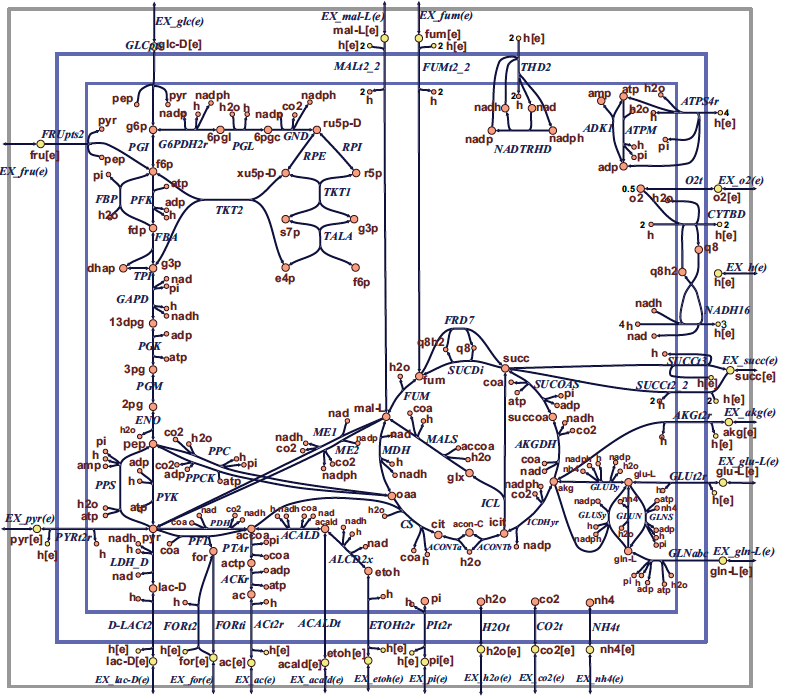

**Figure 1**  **Map of the core E. coli metabolic network. ** Orange circles represent cytosolic metabolites, yellow circles represent extracellular metabolites, and the blue arrows represent reactions.  Reaction name abbreviations are uppercase (blue) and metabolite name abbreviations are lowercase (rust colour).  This flux map was drawn using SimPheny and edited for clarity with Adobe Illustrator. 

## MATERIALS - EQUIPMENT SETUP

Please ensure that all the required dependencies (e.g. , `git` and `curl`) of The COBRA Toolbox have been properly installed by following the installation guide [here](https://opencobra.github.io/cobratoolbox/stable/installation.html). Please ensure that the COBRA Toolbox has been initialised (tutorial_initialize.mlx) and verify that the pre-packaged LP and QP solvers are functional (tutorial_verify.mlx).

## PROCEDURE

## Load E. coli core model

The most direct way to load a model into The COBRA Toolbox is to use the `readCbModel` function. For example, to load a model from a MAT-file, you can simply use the filename (with or without file extension). 

fileName = 'ecoli_core_model.mat';
if ~exist('modelOri','var')
    modelOri = readCbModel(fileName);
end
%backward compatibility with primer requires relaxation of upper bound on
%ATPM
modelOri = changeRxnBounds(modelOri,'ATPM',1000,'u');
model = modelOri;

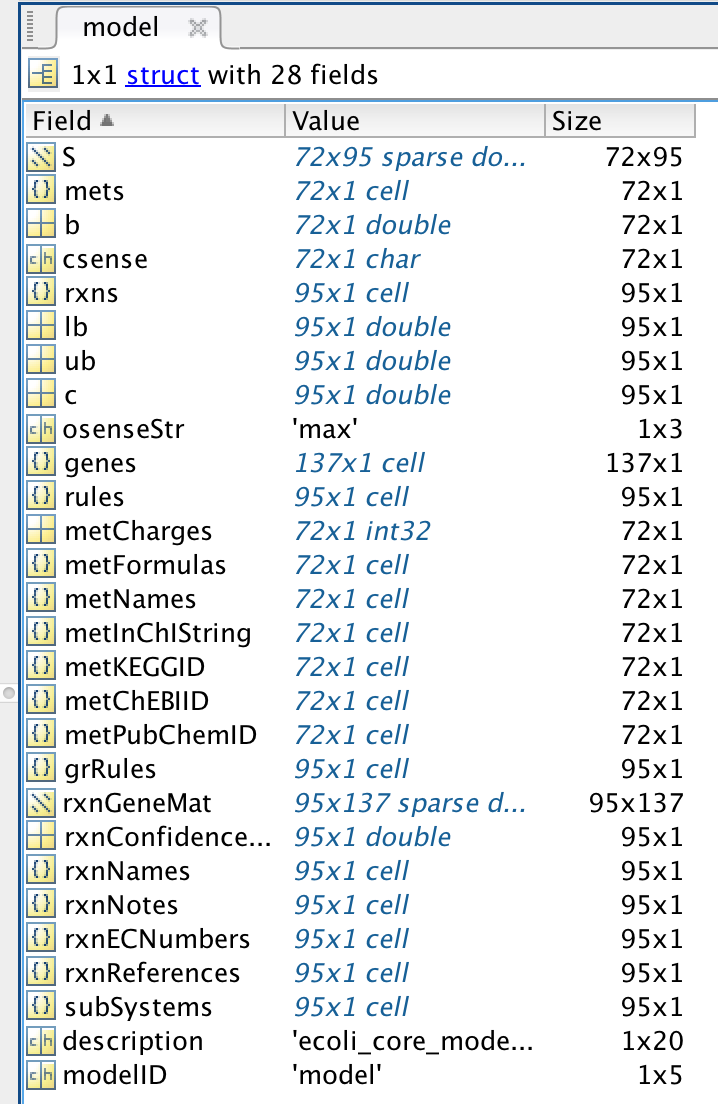

The meaning of each field in a standard model is defined in the [standard COBRA model field definition](https://github.com/opencobra/cobratoolbox/blob/master/docs/source/notes/COBRAModelFields.md).

In general, the following fields should always be present: 

- **S**, the stoichiometric matrix

- **mets**, the identifiers of the metabolites

- **b**, Accumulation (positive) or depletion (negative) of the corresponding metabolites. 0 Indicates no concentration change.

- **csense**, indicator whether the b vector is a lower bound ('G'), upper bound ('L'), or hard constraint 'E' for the metabolites.

- **rxns**, the identifiers of the reactions

- **lb**, the lower bounds of the reactions

- **ub**, the upper bounds of the reactions

- **c**, the linear objective

- **genes**, the list of genes in your model 

- **rules**, the Gene-protein-reaction rules in a computer readable format present in your model.

- **osenseStr**, the objective sense either `'max'` for maximisation or `'min'` for minimisation

## Checking the non-trivial constraints on a model

#### What are the default constraints on the model? 

#### Hint: `printConstraints`

printConstraints(model,-1000,1000)

MinConstraints:
ATPM	8.39
EX_glc(e)	-10
maxConstraints:


## Alternate optimal solutions

The flux distribution calculated by FBA is often not unique.  In many cases, it is possible for a biological system to achieve the same objective value by using alternate pathways, so phenotypically different alternate optimal solutions are possible.   A method that uses FBA to identify alternate optimal solutions is Flux Variability Analysis (FVA)[13].  This is a method that identifies the maximum and minimum possible fluxes through a particular reaction with the objective value constrained to be close to or equal to its optimal value.  Performing FVA on a single reaction using the basic COBRA Toolbox functions is simple.  First, use functions changeRxnBounds, changeObjective, and optimizeCbModel to perform FBA as described in the previous examples.  Get the optimal objective value (FBAsolution.f), and then set both the lower and upper bounds of the objective reaction to exactly this value.  Next, set the reaction of interest as the objective, and use FBA to minimize and maximize this new objective in two separate steps.  This will give the minimum and maximum possible fluxes through this reaction while contributing to the optimal objective value.

#### What is the minimum and maximum rate of the malic enzyme reaction (ME1) when the E. coli core model grows at a maximal rate on succinate as a carbon source?

#### Hint: `changeRxnBounds, printConstraints, optimizeCbModel, changeObjective, solution = optimizeCbModel(model, osenseStr)`

Consider the variability of the malic enzyme reaction (ME1) in E. coli growing on succinate.  The minimum possible flux through this reaction is 0 mmol gDW-1 hr-1 and the maximum is 6.49 mmol gDW-1 hr-1.  In one alternate optimal solution, the ME1 reaction is used, but in another, it is not used at all.  The full code to set the model to these conditions and perform FVA on this reaction is:

model = modelOri;

Change the bounds on the glucose, succinate and o2 exchange reactions

model = changeRxnBounds(model,'EX_glc(e)',0,'l');
model = changeRxnBounds(model,'EX_succ(e)',-20,'l');
model = changeRxnBounds(model,'EX_o2(e)',-1000,'l');

Check the constraints

printConstraints(model,-1000,1000)

MinConstraints:
ATPM	8.39
EX_succ(e)	-20
maxConstraints:


Conduct flux balance analysis to find the maximum growth rate

FBAsolution = optimizeCbModel(model,'max');

Check the maximum growth rate 

FBAsolution.f

ans = 0.8401

Fix the growth rate of the model to the optimal value

model = changeRxnBounds(model,'Biomass_Ecoli_core_N(w/GAM)-Nmet2',FBAsolution.f,'b');

Change the objective `model.c` to optimise the malic enzyme reaction (ME1)

model_ME1 = changeObjective(model,'ME1');

Minimise the rate of the malic enzyme reaction (ME1) subject to the maximum growth rate constraint

FBAsolution_ME1_Min = optimizeCbModel(model_ME1,'min');

Maximise the rate of the malic enzyme reaction (ME1) subject to the maximum growth rate constraint

FBAsolution_ME1_Max = optimizeCbModel(model_ME1,'max');

Check the minimum rate of the malic enzyme reaction (ME1) 

FBAsolution_ME1_Min.f

ans = 0

Check the maximim rate of the malic enzyme reaction (ME1) 

FBAsolution_ME1_Max.f

ans = 6.4924

Observe that the difference between these two is ~6.5 which means that it is possible to have a maximum growth rate at any rate of the malic enzyme reaction (ME1) between 0 and 6.5.

### Display a flux map for alternate solutions for maximum aerobic growth on succinate.

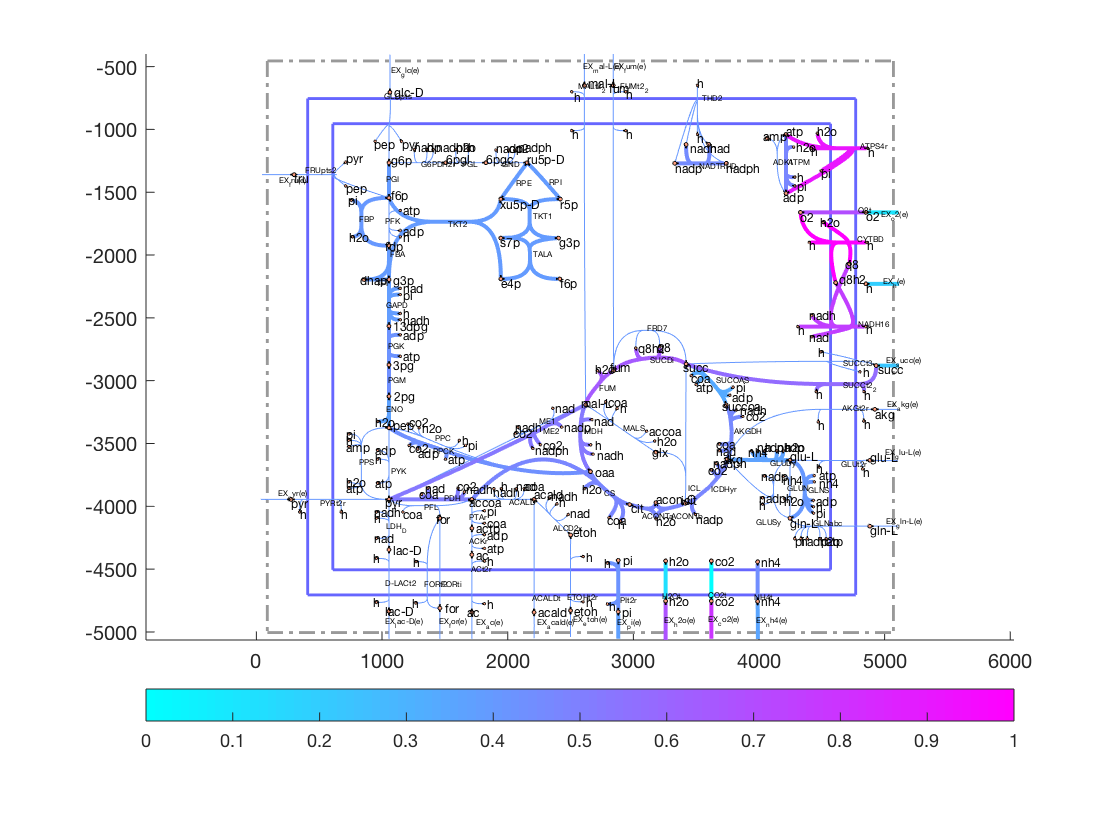

outputFormatOK = changeCbMapOutput('matlab');
map=readCbMap('ecoli_core_map');
options.zeroFluxWidth = 0.1;
options.rxnDirMultiplier = 10;
drawFlux(map, model, FBAsolution_ME1_Min.v, options);

**Figure 4a ** Flux map of an alternate solution for maximum aerobic growth on succinate, with minimal use of ME1, the reaction ME1 that converts L-malate to pyruvate.

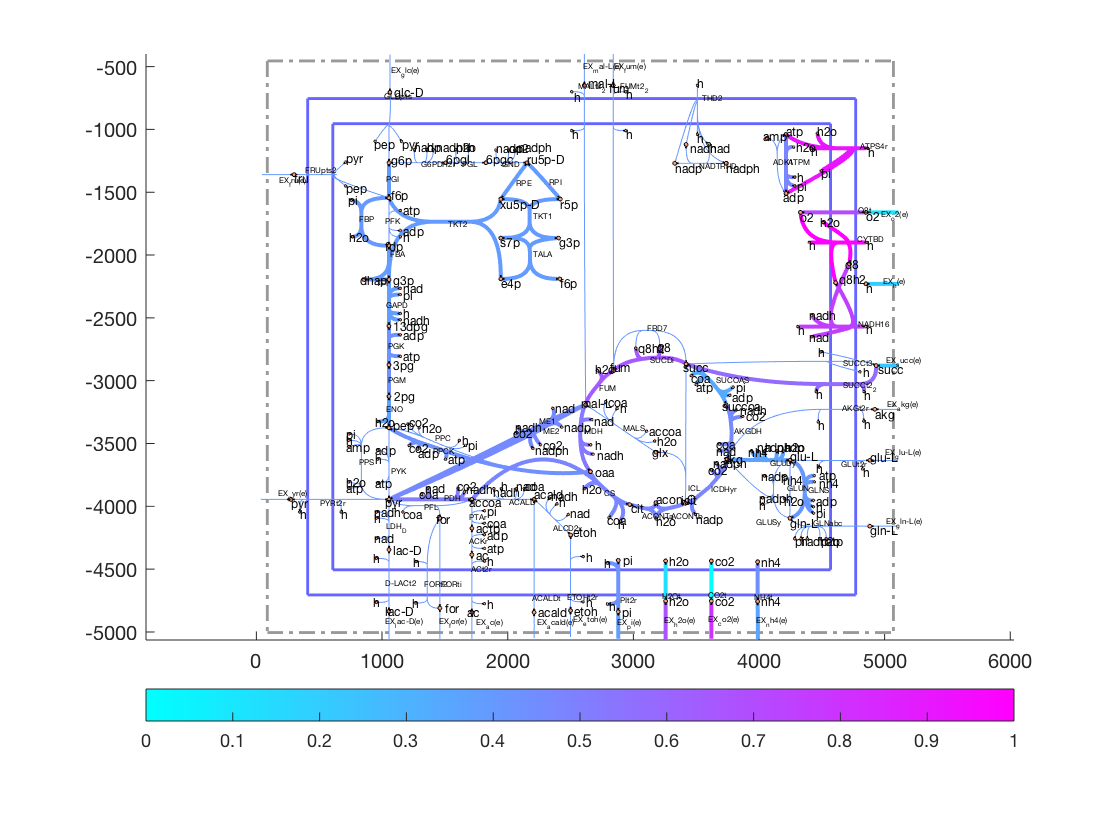

outputFormatOK = changeCbMapOutput('matlab');
map=readCbMap('ecoli_core_map');
options.zeroFluxWidth = 0.1;
options.rxnDirMultiplier = 10;
drawFlux(map, model, FBAsolution_ME1_Max.v, options);

**Figure 4b  ** Flux map of an alternate solution for maximum aerobic growth on succinate, with maximal use of ME1, the reaction ME1 that converts L-malate to pyruvate.

## Systematic evaluation of alternate optima with Flux Variability Analysis

Flux variability analysis minimises and maximises the rate of each reaction in a model to evaluate what range of alternate optima exist for each reaction. The COBRA Toolbox includes a built in function for performing FVA called `fluxVariability`.  This function is useful because, by default, it performs FVA on every reaction in a model.  

#### What reactions vary their optimal flux in the set of alternate optimal solutions to maximum growth of E. coli on succinate? 

#### Hint: create a table with varying reactions using the output from `fluxVariability`

When FVA is performed on every reaction in the E. coli core model for growth on succinate, eight reactions are found to be variable (Table 5).  Inspection of the variable reactions shows that conversion of L-matate to pyruvate may occur through several different pathways, each leading to the same maximum growth rate.  Flux vectors using combinations of these pathways are also valid solutions. Two of these alternate solutions are shown in Figure 4.

FVAresults=cell(size(model.S,2)+1,1);
FVAresults{1,1}='Reaction';
FVAresults{1,2}='Minimum Flux';
FVAresults{1,3}='Maximum Flux';
FVAresults(2:end,1)=model.rxns;
[minFlux, maxFlux, ~, ~] = fluxVariability(model, 100, 'max', [], 0, 1, 'FBA');
for n=1:size(model.S,2)
    FVAresults{n+1,2}=minFlux(n);
    FVAresults{n+1,3}=maxFlux(n);
end
bool=abs(maxFlux-minFlux)>=1e-6;
bool=[true;bool];
FVAresults=FVAresults(bool,:)

FVAresults = 9×3 cell array
    {'Reaction'}    {'Minimum Flux'}    {'Maximum Flux'}
    {'FRD7'    }    {[           0]}    {[    972.7688]}
    {'MDH'     }    {[     13.5650]}    {[     20.0574]}
    {'ME1'     }    {[           0]}    {[      6.4924]}
    {'ME2'     }    {[      7.1738]}    {[     13.6662]}
    {'NADTRHD' }    {[           0]}    {[      6.4924]}
    {'PPCK'    }    {[      3.9263]}    {[     10.4187]}
    {'PYK'     }    {[           0]}    {[      6.4924]}
    {'SUCDi'   }    {[     27.2312]}    {[        1000]}


**Table 5 ** Variable reactions for growth on succinate (uptake rate = 20 mmol gDW-1 hr-1) under aerobic conditions.  The minimum and maximum possible flux for every reaction was calculated at the maximum growth rate and only reactions with variable fluxes are shown here.  

#### Are there any reactions that are not used in one optimal solution but used in another optimal solution? 

#### Hint: study the flux variablity analysis results

FRD7 (fumarate reductase), ME1 (malic enzyme (NAD)), NADTRHD (NAD transhydrogenase), and PYK (pyruvate kinase).

#### What are the computational and biochemical aspects to consider when interpreting these alternate optimal solutions?

#### Hint: the flux span for some reactions is far larger than for other reactions

FRD7 (fumarate reductase) and SUCDi (succinate dehydrogenase) always have highly variable fluxes in this model because they form a cycle that can carry any flux.  Physiologically, these fluxes are not relevant, as they are a computational artefact of not enforcing energy conservation and the second law of thermodynamics.  The other variable reactions are MDH (malate dehydrogenase), ME1 (malic enzyme (NAD)), ME2 (malic enzyme (NADP)), NADTRHD (NAD transhydrogenase), PPCK (phosphoenolpyruvate carboxykinase), and PYK (pyruvate kinase) and represent biochemical alternate optima.

#### In E.coli core, what reactions vary their optimal flux in the set of alternate optimal solutions where  PYK (pyruvate kinase) is always at a maximum rate? 

#### Hint: `fluxVariability, drawFlux`

model = modelOri;
model_PYK = changeObjective(model,'PYK');

FVAresults_PYK=cell(size(model.S,2)+1,1);
FVAresults_PYK{1,1}='Reaction';
FVAresults_PYK{1,2}='Minimum Flux';
FVAresults_PYK{1,3}='Maximum Flux';
FVAresults_PYK(2:end,1)=model.rxns;
[minFlux, maxFlux, ~, ~] = fluxVariability(model_PYK, 100, 'max', [], 0, 1, 'FBA');
for n=1:size(model.S,2)
    FVAresults_PYK{n+1,2}=minFlux(n);
    FVAresults_PYK{n+1,3}=maxFlux(n);
end
bool=abs(maxFlux-minFlux)>=1e-6;
bool=[true;bool];
FVAresults_PYK=FVAresults_PYK(bool,:)

FVAresults_PYK = 27×3 cell array
    {'Reaction'}    {'Minimum Flux'}    {'Maximum Flux'}
    {'ADK1'    }    {[    146.6100]}    {[    166.6100]}
    {'AKGDH'   }    {[           0]}    {[     20.0000]}
    {'ATPS4r'  }    {[    135.0000]}    {[    135.0000]}
    {'FORt2'   }    {[           0]}    {[  4.0000e-06]}
    {'FORti'   }    {[           0]}    {[  4.0000e-06]}
    {'FRD7'    }    {[           0]}    {[    980.0000]}
    {'G6PDH2r' }    {[           0]}    {[  1.3333e-06]}
    {'GLUDy'   }    {[ -7.6923e-08]}    {[  1.0000e-06]}
    {'GND'     }    {[           0]}    {[  1.3333e-06]}
    {'ICDHyr'  }    {[  9.3875e-29]}    {[     20.0000]}
    {'ICL'     }    {[           0]}    {[     20.0000]}
    {'MALS'    }    {[           0]}    {[     20.0000]}
    {'MDH'     }    {[     20.0000]}    {[     40.0000]}
    {'NADH16'  }    {[    100.0000]}    {[    100.0000]}
    {'NADTRHD' }    {[           0]}    {[     20.0000]}


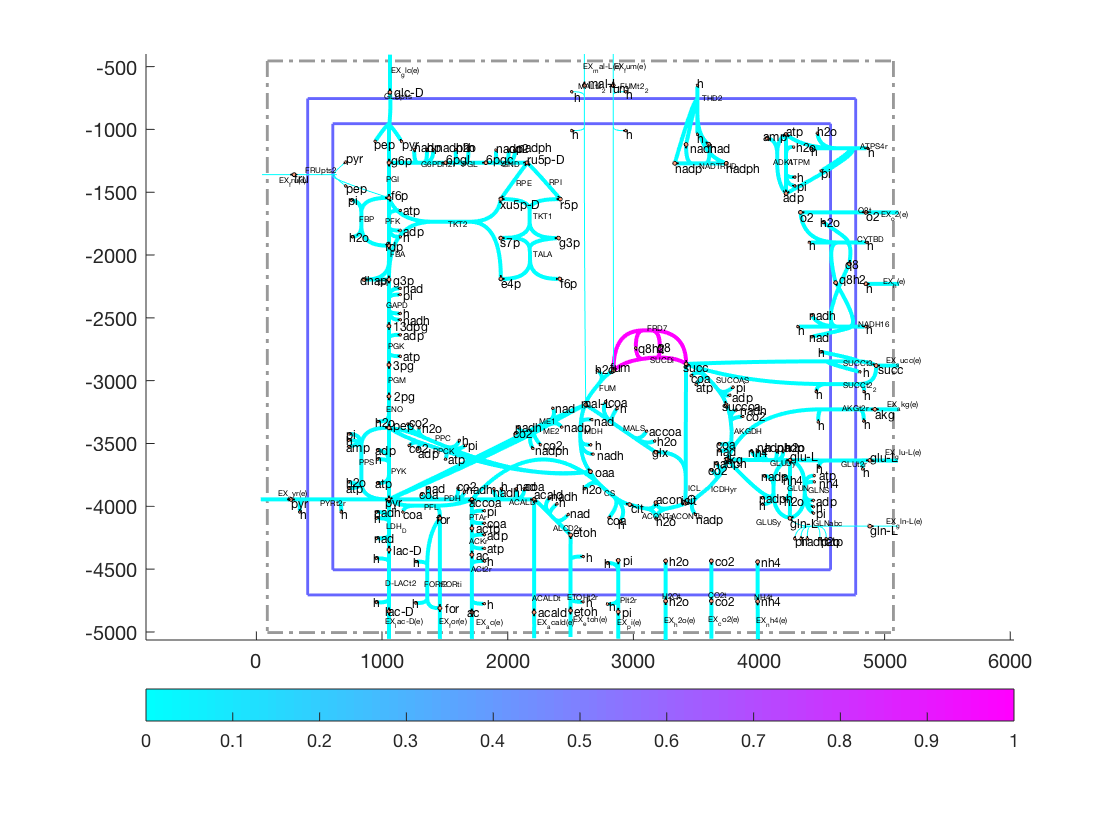

drawFlux(map, model, maxFlux - minFlux, options); 

**Figure 4b ** Flux maps displaying the reactions with non-zero flux span for maximum aerobic growth on pyruvate.

## TIMING

*1 hrs*

## ANTICIPATED RESULTS

Understanding that, often, many alternate optimal flux vectors can give rise to the same optimal objective to a flux balance analysis problem.

## *Acknowledgments*

Part of this tutorial was originally written by Jeff Orth and Ines Thiele for the publication "What is flux balance analysis?"

## REFERENCES

1. Orth, J.D., Fleming, R.M. & Palsson, B.O. in EcoSal - Escherichia coli and Salmonella Cellular and Molecular Biology. (ed. P.D. Karp) (ASM Press, Washington D.C.; 2009).

2. Mahadevan, R. & Schilling, C.H. The effects of alternate optimal solutions in constraint-based genome-scale metabolic models. Metabolic engineering 5, 264-276 (2003).

3. Laurent Heirendt & Sylvain Arreckx, Thomas Pfau, Sebastian N. Mendoza, Anne Richelle, Almut Heinken, Hulda S. Haraldsdottir, Jacek Wachowiak, Sarah M. Keating, Vanja Vlasov, Stefania Magnusdottir, Chiam Yu Ng, German Preciat, Alise Zagare, Siu H.J. Chan, Maike K. Aurich, Catherine M. Clancy, Jennifer Modamio, John T. Sauls, Alberto Noronha, Aarash Bordbar, Benjamin Cousins, Diana C. El Assal, Luis V. Valcarcel, Inigo Apaolaza, Susan Ghaderi, Masoud Ahookhosh, Marouen Ben Guebila, Andrejs Kostromins, Nicolas Sompairac, Hoai M. Le, Ding Ma, Yuekai Sun, Lin Wang, James T. Yurkovich, Miguel A.P. Oliveira, Phan T. Vuong, Lemmer P. El Assal, Inna Kuperstein, Andrei Zinovyev, H. Scott Hinton, William A. Bryant, Francisco J. Aragon Artacho, Francisco J. Planes, Egils Stalidzans, Alejandro Maass, Santosh Vempala, Michael Hucka, Michael A. Saunders, Costas D. Maranas, Nathan E. Lewis, Thomas Sauter, Bernhard Ø. Palsson, Ines Thiele, Ronan M.T. Fleming, **Creation and analysis of biochemical constraint-based models: the COBRA Toolbox v3.0**, Nature Protocols, volume 14, pages 639–702, 2019 [doi.org/10.1038/s41596-018-0098-2](https://doi.org/10.1038/s41596-018-0098-2).

4. Thiele, I., Fleming, R. M. T., Bordbar, A., Schellenberger, J., & Palsson, B. Ø. (2010). Functional Characterization of Alternate Optimal Solutions of Escherichia coli’s Transcriptional and Translational Machinery. Biophysical Journal, 98(10), 2072–2081. https://doi.org/10.1016/j.bpj.2010.01.060